# Connect to a ROS-enabled Robot from Simulink®

You can use Simulink to connect to a ROS-enabled physical robot or to a ROS-enabled robot simulator such as [Gazebo](http://gazebosim.org/). This example shows how to configure Simulink to connect to a separate robot simulator using ROS. It then shows how to send velocity commands and receive position information from a simulated robot.

Simulink를 사용하여 ROS 지원 물리적 로봇 또는 Gazebo와 같은 ROS 지원 로봇 시뮬레이터에 연결할 수 있습니다. 이 예는 ROS를 사용하여 별도의 로봇 시뮬레이터에 연결하도록 Simulink를 구성하는 방법을 보여줍니다. 그런 다음 시뮬레이션된 로봇에서 속도 명령을 보내고 위치 정보를 받는 방법을 보여줍니다

You can follow the steps in the example to create your own model, or you can use this completed [version](matlab:robotROSConnectToRobotExample) instead.

예제의 단계에 따라 고유한 모델을 생성하거나 이 완성된 버전을 대신 사용할 수 있습니다.ss

open_system('robotROSConnectToRobotExample');

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a), [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b), [Get Started with ROS in Simulink](docid:ros_ug.mw_f3eb0f51-9abd-4add-9edc-c8d9e579924e).

## Robot Simulator

Start a ROS-based simulator for a differential-drive robot. The simulator receives and sends messages on the following topics:

차동 구동 로봇용 ROS 기반 시뮬레이터를 시작합니다. 시뮬레이터는 다음 주제에 대한 메시지를 수신 및 전송합니다.

- Sends `nav_msgs/Odometry` messages to the `/odom` topic

- nav_msgs/Odometry 메시지를 /odom 주제로 보냅니다

- Receives `geometry_msgs/Twist` velocity command messages on the /`mobile_base/commands` or `/cmd_vel` topic, based on the ROS-based simulator

- ROS 기반 시뮬레이터를 기반으로 /mobile_base/commands 또는 /cmd_vel 주제에 대한 geometry_msgs/Twist 속도 명령 메시지 수신

You can choose one of two options for setting up the ROS-based simulator.

ROS 기반 시뮬레이터를 설정하는 두 가지 옵션 중 하나를 선택할 수 있습니다.

**Option A: Simulator in MATLAB®**

Use a simple MATLAB-based simulator to plot the current location of the robot in a separate figure window.

간단한 MATLAB 기반 시뮬레이터를 사용하여 별도의 그림 창에 로봇의 현재 위치를 플로팅합니다.

- Enter [`rosinit`](docid:ros_ref.bupf5_j_1) at the MATLAB command line. This creates a local *ROS master* with network address (URI) of [`http://localhost:11311`](http://localhost:11311)

- MATLAB 명령줄에 rosinit를 입력합니다. 이것은 네트워크 주소(URI)가 http://localhost:11311인 로컬 ROS 마스터를 생성합니다.

- Enter `ExampleHelperSimulinkRobotROS` to start the Robot Simulator:

- 로봇 시뮬레이터를 시작하려면 ExampleHelperSimulinkRobotROS를 입력하십시오.

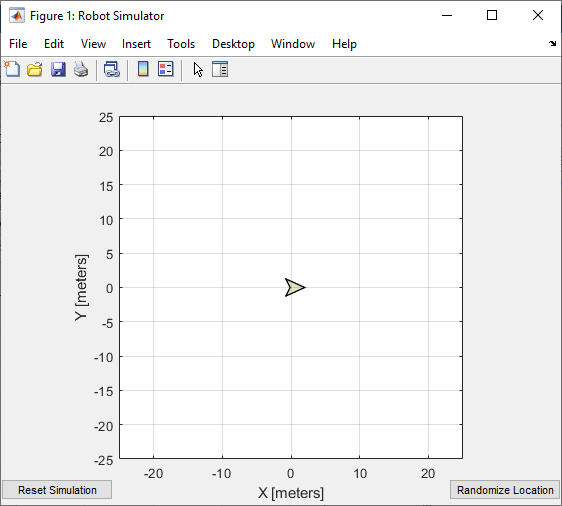

- **Note: **The `geometry_msgs/Twist` velocity command messages are received on the /`mobile_base/commands/velocity` topic.

**Option B: Gazebo Simulator**

Use a simulated TurtleBot® in Gazebo. 

- See [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_aefba829-05e2-4e06-9209-900daf7fb987) for instructions on setting up the Gazebo environment. In the Ubuntu® desktop in the virtual machine, click the "Gazebo Empty" icon.

- Gazebo 환경 설정에 대한 지침은 Gazebo 및 시뮬레이션된 TurtleBot 시작하기를 참조하세요. 가상 머신의 Ubuntu® 데스크탑에서 "Gazebo Empty" 아이콘을 클릭합니다.

- Note the network address (URI) of the ROS master. It will look like `http://192.168.84.128:11311`, but with your specific IP address.

- ROS 마스터의 네트워크 주소(URI)를 기록해 둡니다. http://192.168.84.128:11311처럼 보이지만 특정 IP 주소를 사용합니다.

- Verify that the Gazebo environment is properly set up by typing the `rostopic` `list` in the Ubuntu terminal window. You should see a list of topics, including `/cmd_vel `and `/odom`.

- Ubuntu 터미널 창에 rostopic 목록을 입력하여 Gazebo 환경이 제대로 설정되었는지 확인합니다. /cmd_vel 및 /odom을 포함한 주제 목록이 표시되어야 합니다.

- **Note:** The `geometry_msgs/Twist` velocity command messages are received on the /cmd_vel topic.

- 참고: geometry_msgs/Twist 속도 명령 메시지는 /cmd_vel 주제에서 수신됩니다.

## Configure Simulink to Connect to the ROS Network

**1.** From the **Simulation **tab, select **ROS Toolbox*** > ***ROS Network**.

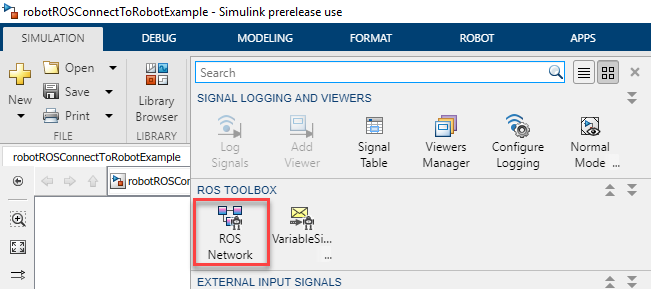

**2.** In the **ROS Master (ROS 1)** section, select `Custom` from the **Network Address** dropdown.

ROS 마스터(ROS 1) 섹션의 네트워크 주소 드롭다운에서 사용자 지정을 선택합니다.

- Option A (MATLAB Simulator): Ensure that the **Hostname/IP Address** is set to `localhost`, and **Port** is set to `11311`.

- 옵션 A(MATLAB 시뮬레이터): 호스트 이름/IP 주소가 localhost로 설정되어 있고 포트가 11311로 설정되어 있는지 확인하십시오.

- Option B (Gazebo Simulator): Specify the IP address and port number of the ROS master in Gazebo. For example, if it is `http://192.168.60.165:11311`, then enter `192.168.60.165` in the **Hostname/IP address** box and `11311` in the **Port** box.

- 옵션 B(Gazebo Simulator): Gazebo에서 ROS 마스터의 IP 주소와 포트 번호를 지정합니다. 예를 들어 http://192.168.60.165:11311인 경우 호스트 이름/IP 주소 상자에 192.168.60.165를 입력하고 포트 상자에 11311을 입력합니다.

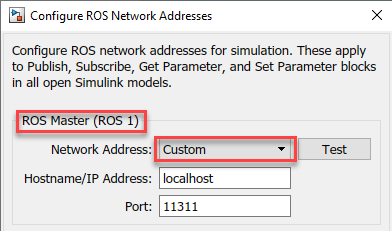

## Send Velocity Commands To the Robot

Create a publisher that sends control commands (linear and angular velocities) to the simulator. Make these velocities adjustable by using **Slider Gain** blocks.

ROS uses a right-handed coordinate system, so X-axis is forward, Y-axis is left, and Z-axis is up. Control commands are sent using a `geometry_msgs/Twist` message, where `Linear.X` indicates linear forward velocity (in m/s), and `Angular.Z` indicates angular velocity around the Z-axis (in rad/s).

### Configure a Publisher Block

- Open a new Simulink model. 

- From the **ROS Toolbox **> **ROS** tab in the Library Browser, drag a **Publish** block to the model. Double-click the block.

- Set **Topic source** field to **Select From ROS network**. Select a topic based on the simulator as shown below.

- Option A (MATLAB Simulator): Click **Select** next to **Topic**, select `/mobile_base/commands/velocity`, and click **OK**. Note that the message type (`geometry_msgs/Twist`) is set automatically.

- Option B (Gazebo Simulator): Click **Select** next to **Topic**, select `/cmd_vel`, and click **OK**. Note that the message type (`geometry_msgs/Twist`) is set automatically.

### Configure a Message Block

- From the **ROS Toolbox** > **ROS** tab in the Library Browser, drop a **Blank Message** block to the model. Double-click the block.

- Click **Select** next to **Message type** and select `geometry_msgs/Twist`.

- Set **Sample time** to `0.01` and click **OK**.

### Configure Message Inputs

- From the **Simulink*** > ***Signal Routing** tab in the Library Browser, drag a **Bus Assignment** block to the model.

- Connect the `Msg` output of the **Blank Message** block to the `Bus` input of the **Bus Assignment **block, and the `Bus` output to the `Msg` input of the **Publish** block. 

- From the **Modeling** tab, click **Update Model** to ensure that the bus information is correctly propagated. Ignore the error, "Selected signal 'signal1' in the Bus Assignment block 'untitled/Bus Assignment' cannot be found in the input bus signal", if it appears. The next step will resolve this error.

- Double-click the **Bus Assignment** block. Select `???` `signal1` in the right list box and click **Remove**. In the left list box, expand both Linear and Angular properties. Select **Linear*** > ***X** and **Angular*** > ***Z** and click **Select**. Click **OK** to close the block mask.

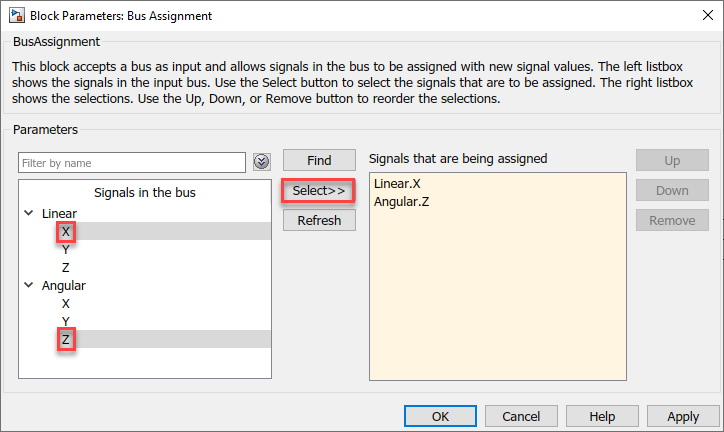

- Add a **Constant** block, a **Gain** block, and two **Slider Gain** blocks. Connect them together as shown in the figure, and set the **Gain** value to `-1.`

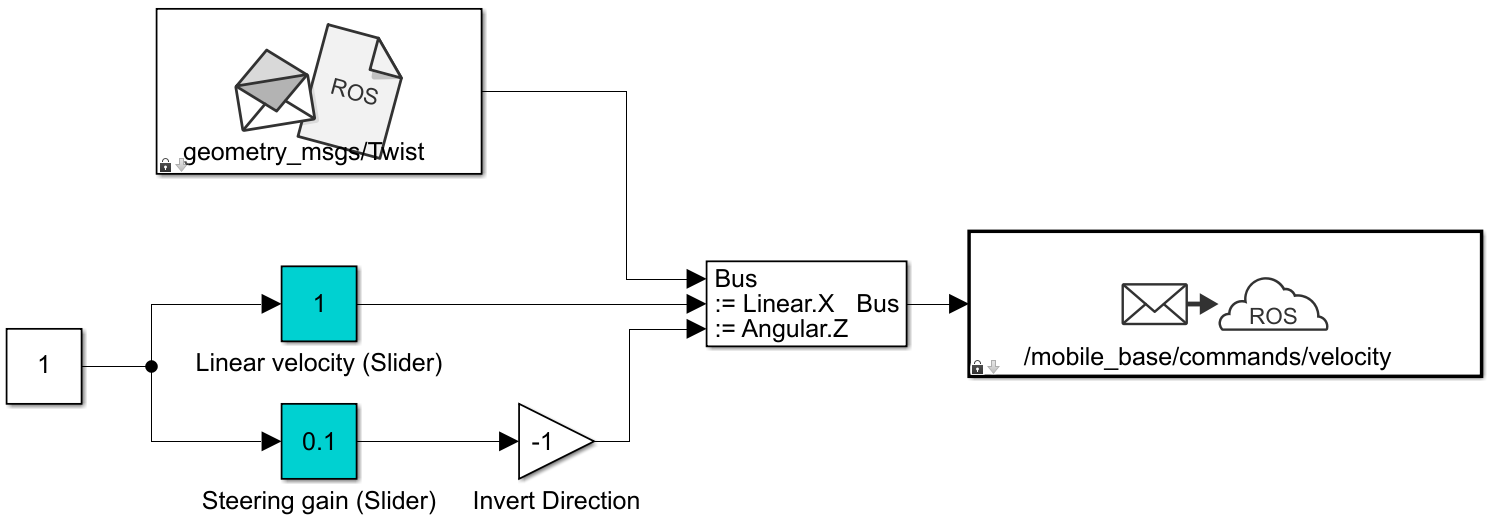

- Set the limits and current parameters of the linear velocity slider to `0.0` to `2.0`, and `1.0` respectively. Set the corresponding parameters of the steering gain slider to `-1.0` to `1.0`, and `0.1`.

## Receive Location Information from the Robot

Create a subscriber to receive messages sent to the `/odom` topic. Extract the location of the robot and plot it's path in the XY-plane.

### Configure a Subscriber block

- From the **ROS** **Toolbox** > **ROS **tab in the Library Browser, drag a **Subscribe** block to the model. Double-click the block.

- Set **Topic source** to **Select From ROS network**, and click **Select** next to the **Topic** box. Select "/odom" for the topic and click **OK**. Note that the message type `nav_msgs/Odometry` is set automatically.

### Read Message Output

- From the **Simulink*** > ***Signal Routing** tab in the Library Browser, drag a **Bus Selector** block to the model.

- Connect the output port of the **Subscribe** block to the input port of the **Bus Selector** block. In the **Modeling** tab, click **Update Model **to ensure that the bus information is correctly propagated.

- Double-click the **Bus Selector** block. Select `???` `signal1` and `???` `signal2` in the right listbox and click **Remove**. In the left listbox, expand **Pose*** > ***Pose*** > ***Position** and select **X** and **Y**. Click **Select** and then **OK**.

- From the **Simulink*** > ***Sinks** tab in the Library Browser, drag an **XY Graph** block to the model. Connect the `X` and `Y` output ports of the **Bus Selector** block to the input ports of the **XY Graph** block. 

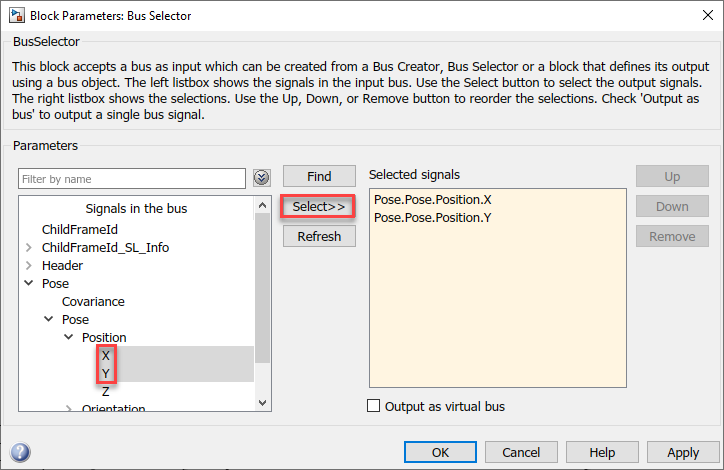

This figure shows the completed model. A [pre-configured model](matlab:robotROSConnectToRobotExample) is included for your convenience.

- **Note:** The Publisher block in this model uses the `/mobile_base/commands/velocity` topic for use with MATLAB simulator option. For Gazebo simulator option, select the `/cmd_vel` topic as shown above.

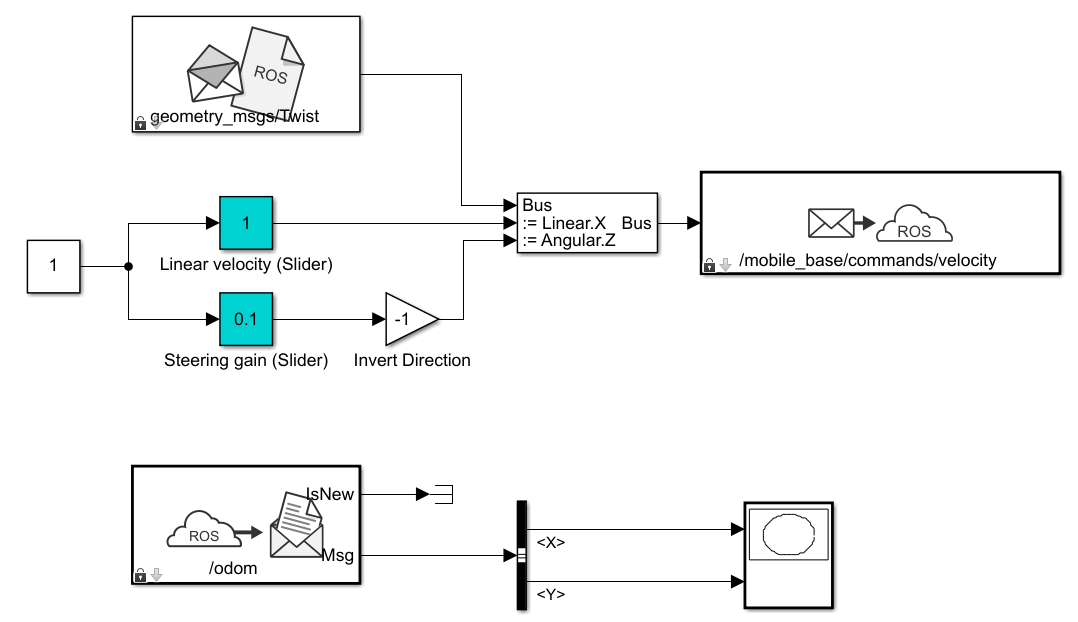

## Configure and Run the Model

- From the **Modeling **tab, click **Model Settings**. In the **Solver** pane, set **Type** to **Fixed-step** and **Fixed-step size** to `0.01`.

- Set simulation Stop time to `Inf`.

- Click **Run** to start the simulation.

- In both the simulator and XY plot, you should see the robot moving in a circle.

- While the simulation is running, change the values of **Slider Gain** blocks to control the robot. Double-click the **XY Graph** block and change the `X` and `Y` axis limits if needed. (You can do this while the simulation is running.)

- To stop the simulation, click **Stop**.

*Copyright 2014-2020 The MathWorks, Inc.*